# Lab 3

#### *Asking a Statistical Question*

## Problem 1: Temperature

___________________________________________________________________________

In this example, we are looking at the temperature readings associated with some ambiguous experiment. The temperature should remain around 12 Kelvin for the experiment to run reliably, and the data we see tends to be consistently 12K within the 0.4 degree precision of the instruments. Essentially, our temperature distribution is a Gaussian centered at 12K with a standard deviation of 0.4. However, there are some occurrences where the thermal control system didn't work and the temperature was not near 12K. Additionally, there are various glitches in the thermometry which give anomalously high and low readings. Such data points should be identified and thrown out. ___________________________________________________________________________

### A. Identifying and Removing "Bad" Data

#### EXPLORING APPROPRIATE PLOTS:

Temperature simulation of 100k 'good' data points, with the addition of several 'bad' data points:

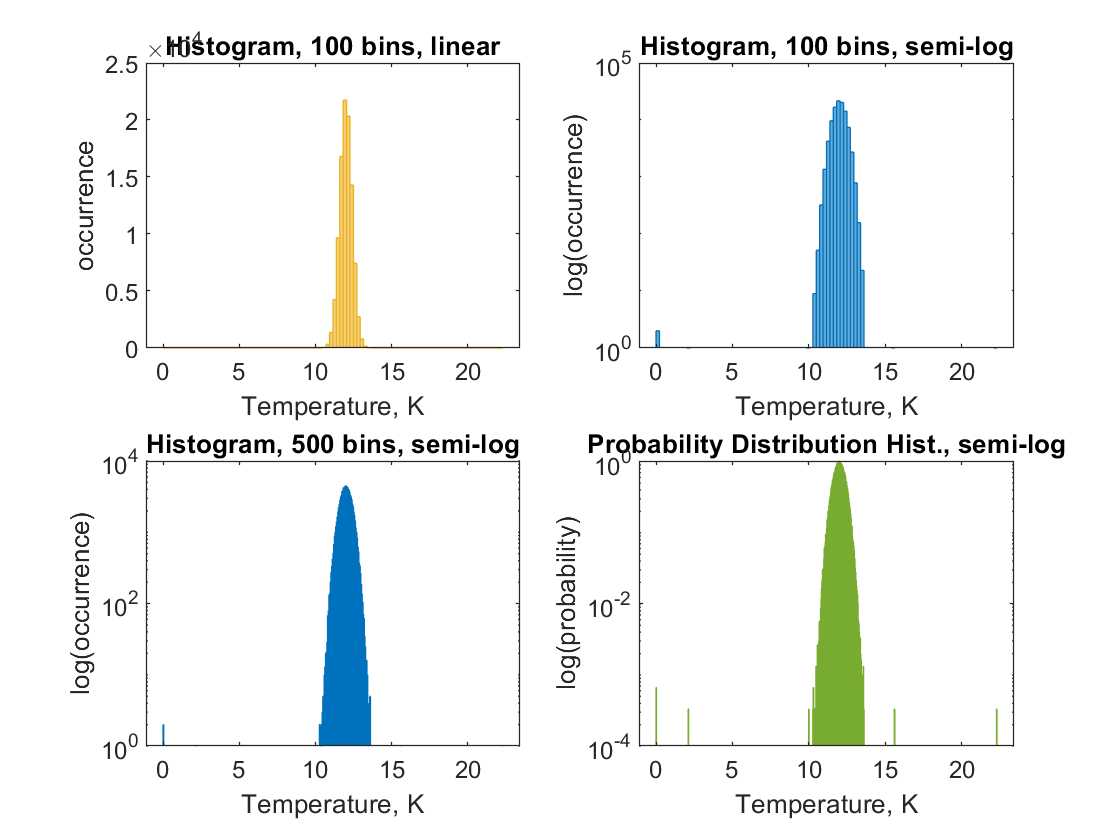

pd = makedist("Normal","mu",12,"sigma",0.4);
badpts = [10.,10.3,2.1,0.,0.,15.6,22.3,12.7];
dist = random(pd,1,100000);

d = [dist badpts];

subplot(2,2,1)
histogram(d,100,"FaceColor",'#EDB120',"EdgeColor",'#EDB120')
title('Histogram, 100 bins, linear')
xlabel('Temperature, K')
ylabel('occurrence')

subplot(2,2,2)
histogram(d,100,"FaceColor",'#0072BD',"Edgecolor",'#0072BD')
set(gca,'YScale','log')
title('Histogram, 100 bins, semi-log')
xlabel('Temperature, K')
ylabel('log(occurrence)')

subplot(2,2,3)
histogram(d,500,'Edgecolor','#0072BD')
set(gca,'YScale','log')
title('Histogram, 500 bins, semi-log')
xlabel('Temperature, K')
ylabel('log(occurrence)')

subplot(2,2,4)
histogram(d,'Normalization','pdf','Edgecolor','#77AC30')
set(gca,"YScale",'log')
title('Probability Distribution Hist., semi-log')
xlabel('Temperature, K')
ylabel('log(probability)')

#### THE STATISTICAL QUESTION:

My goal is to separate my bad data points out of my distribution. For every data point in my distribution, what is the likelihood that it's explained by the background? 

Also, once I know what that probability is, what is my threshold to remove the data point?

#### THE STATISTICAL QUESTION, IN MATH:

The background is Gaussian with $\sigma =0\ldotp 4$ and $\mu =12$; its probability distribution is described by: $f\left(x\right)=\frac{1}{0\ldotp 4\sqrt{2\pi }}e^{-\frac{1}{2}{\left(\frac{x-12}{0\ldotp 4}\right)}^2 }$

$X\sigma =\int_a^{\infty } f\left(x\right)\mathrm{dx}$. 

$X=?$ for all points in the distribution. 

Using those values of $\sigma$, determine a threshold to remove bad data points. 

#### APPLICATION OF THE STATISTICAL QUESTION:

Here I'm finding the probabilities of occurrence in the background distribution pd of the values in my histograms. Each probability is recorded in the vector "probabilities."

l = length(d);
probabilities = zeros(1,l);

for k = 1:l
    probabilities(k) = cdf(pd,d(k));
end

Now I'm converting the probabilities into "sigmas" using the norminv function. I'm taking the aboslute value of the sigmas to make my life simpler when it comes to determining the threshold. 

sigmas = zeros(1,l);

for k = 1:l
    sigmas(k) = abs(norminv(probabilities(k)));
end

The last 8 entries in "probabilities" and "sigmas" correspond to the 'bad' points. These are the values of their sigmas: 

for k = l-7:l
    sigmas(k)
end

ans = 5

ans = 4.2500

ans = 24.7500

ans = 30.0000

ans = 30.0000

ans = Inf

ans = Inf

ans = 1.7500

Several 'bad' points have low sigma values, but I'll take my threshold sigma value to be 4.2 sigma and create a for loop with an 'if' condition to eliminate the points that exceed my threshold. 

for k = 1:l
    if sigmas(k) > 4.2
        d(k) = NaN;
    end
end

dnew = rmmissing(d);

RealGood = [length(dist)-2;2];
RealBad = [1;length(badpts)-1];
FoundBad = [2;length(d)-length(dnew)-2];
FoundGood = [length(dnew)-1;1];

rownames = {'FoundGood';'FoundBad'};

T = table(RealGood,RealBad,'RowNames',rownames)

T = 2×2 table
                 RealGood    RealBad
                 ________    _______

    FoundGood     99998         1   
    FoundBad          2         7   


The table compares the number of found and real 'good' and 'bad' points. 

I found the values in this truth table by comparing the length of my thresholded points to my original data set and cross-referencing with the amount of 'bad' points that would make it through the 'if' loop given my condition. 

### B. On Omissions

An omission is when I throw out a piece of 'good' data. 

The number of omissions increases as my threshold decreases, since my threshold is the sigma value, and sigma decreases as occurrence increases. For instance, if instead I made my threshold 3 sigma,

d = [dist badpts];

for k = 1:l
    if sigmas(k) > 3
        d(k) = NaN;
    end
end

dnew2 = rmmissing(d);
th42 = length(dnew)

th42 = 99999

th3 = length(dnew2)

th3 = 99762

diff = th42-th3

diff = 237

When I decrease my threshold from 4.2 to 3, the number of omissions increases by 237 (I can use this number since no new 'bad' data points are caught in this threshold). 

The number of omissions is predictable. Had I gone through all of my sigma data points, I would have been able to determine the exact number of omissions prior to thresholding d. Going through all 100008 data points to predict every omission, while technically possible, would be time consuming and possibly soul killing. 

This is only possible since I know which of my data points are 'bad.' With no information on 'good' vs. 'bad' data points, it's not possible to know which values are correctly thrown out and which are omitted.

### C. Mistakes of Commission

A mistake of commission is when a bad data point remains in the edited data. 

My algorithm (threshold = 4.2) does have a mistake of commission. There is one 'bad' data point that was found to be 'good.'

Mistakes of commission are avoidable. If I took my threshold to be 1.74, all of the bad data points would be taken out since all of their "sigmas" would be greater than the threshold value. However, this would also cause a great deal of valuable data to be omitted.

Essentially, there is a trade-off between mistakes of commission and omissions. As the threshold is increases, there are fewer omissions but more mistakes of commission. 

## Problem 2: Asteroids

___________________________________________________________________________

This example looks for asteroids within a two-dimensional distribution with a 1 arcsecond RMS. The distribution is caused by imperfect alignment due to atmospheric and instrumental effects. 

Given a potential asteroid, there is some movement between images not caused by the background distribution. My goal is to find the distance of the "5 sigma" detection of movement.

___________________________________________________________________________

### 1. The Question, in Words

To have a "5 sigma" probability detection of movement for a potential asteroid, what is the distance I would have to measure to achieve that level of detection?

### 2. The Question, in Math

To express my statistical question in math, I need to determine an analytic description of my 2D Gaussian distribution. 

The amplitude of my distribution, which I assume is a vector of two identical "X" distribution components, is $\sqrt{2X^2 }$. Such a distribution is equivalent to the square root of a chi-square distribution. MATLAB doesn't have functions to create 2D Gaussian or chi-square distributions, so I have to go one step further. 

An exponential distribution with $\lambda =\frac{1}{2}$ is also equivalent to a chi-square distribution, so the amplitude of a 2D Gaussian can be expressed as the square root of an exponential distribution  with $\lambda =\frac{1}{2}$, assuming the "X"s are standard normal distributions. If not, the exponential distribution has to be multiplied by a factor of $\sigma$ to maintain normalization. 

$f\left(x\right)=\frac{1}{2}e^{-\frac{x}{2}} \;|\;x\ge 0$ is the probability distribution function of an exponential function with $\lambda =\frac{1}{2}$. 

$\mathrm{Amp}=\sqrt{\sigma \cdot \frac{1}{2}e^{-\frac{x}{2}} }$, the probability distribution I will consider for this problem. 

My question, in math, is this: 

$x=?$ for $"5\sigma "=\sqrt{\sigma \cdot \frac{1}{2}e^{-\frac{x}{2}} }$ 

Note: the $\mathrm{RMS}=1$, so I take "X" to be a standard normal distribution. 

### 3. Finding the Distance Corresponding to 5$\sigma$

Analytically solving for x: 


$$\mathrm{Probability}\;\left(\mathrm{corresponding}\;\mathrm{to}\;5\sigma \right)=\sqrt{\frac{1}{2}e^{-\frac{x}{2}} }$$



$${2\cdot \mathrm{prob}}^2 =e^{-\frac{x}{2}} \;$$



$$\mathrm{ln}\left(2\cdot {\mathrm{prob}}^2 \right)=-\frac{x}{2}$$



$$-2\cdot \mathrm{ln}\left(2\cdot {\mathrm{prob}}^2 \right)=x$$


Now solving for x using MATLAB:

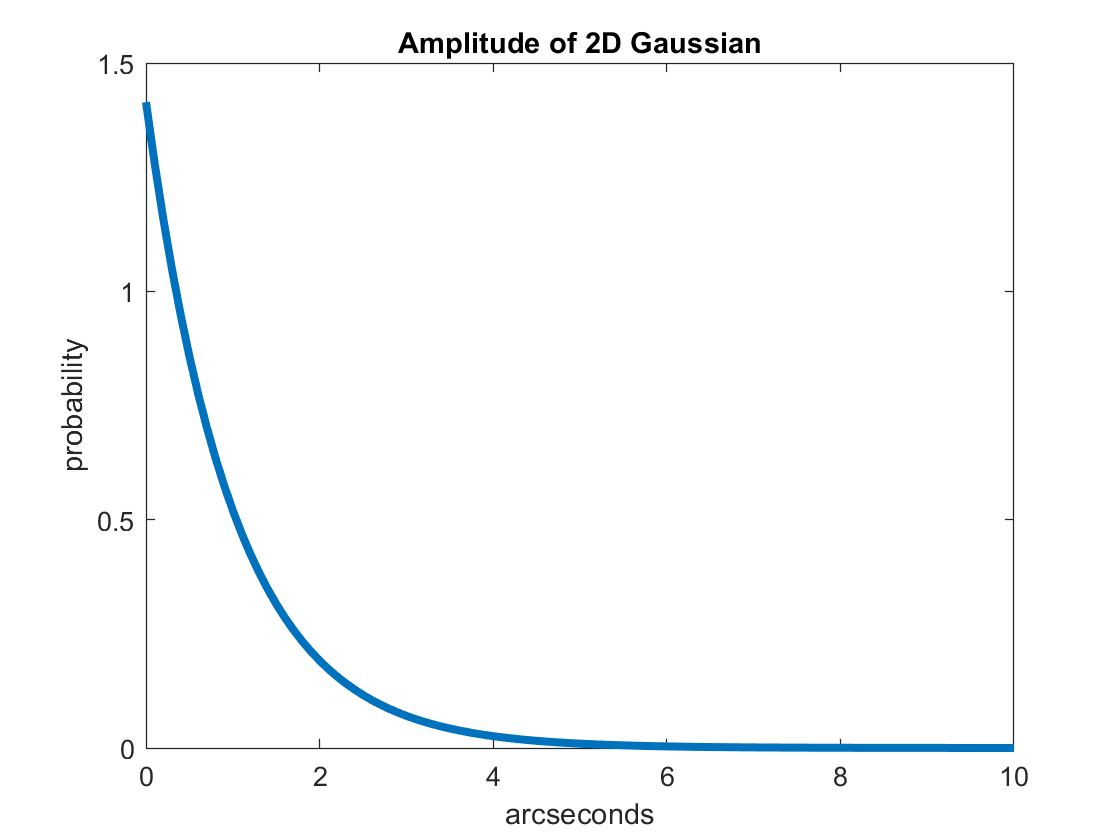

x = 0:0.1:10;
expon = makedist("Exponential","mu",0.5);
expvals = pdf(expon,x);
amp = sqrt(expvals);

subplot(1,1,1)
plot(x,amp,"LineWidth",3);
title("Amplitude of 2D Gaussian")
xlabel("arcseconds")
ylabel("probability")


sig = -5;
p = normcdf(sig)

p = 2.8665e-07


X = -2*log(2*(p^2))

X = 58.8737

Based on my equation, x = 58.9 arcseconds.

## Problem 3: Cosmic Rays

___________________________________________________________________________

One of the key backgrounds for gamma-ray telescopes are cosmic rays. Cosmic rays are charged particles (typically protons or electrons). Because of their charge, cosmic rays spiral in the magnetic field of the galaxy. From the perspective of the Earth they appear to be coming uniformly from all directions like a high energy gas, and the direction the cosmic ray is travelling when it reaches the Earth tells us nothing about where it came from. However, at trillion electron volt energies and above, the spiral loops are fairly big and the sun and the moon will block cosmic rays. This means the sun and the moon appear as holes in the cosmic ray sky.

For this example, on a moon sized patch on the sky we normally have a cosmic ray rate of 1 cosmic ray per minute. We can observe where the moon is for 8 hours per night for 15 days and see 6800 cosmic rays.

___________________________________________________________________________

### 1. The Question, in Words

Over a period of 15 days, observing for 8 hours per day, what is the significance of seeing a total of 6800 cosmic rays? What is the probability that the background is equally or more signal-like than the observation?

### 2. The Question, in Math

#### THE QUESTION:

Given a probability distribution characterized by $P\left(k\;\mathrm{events}\;\mathrm{in}\;\mathrm{interval}\;t\right)=\frac{{\left(r\cdot t\right)}^k e^{-\mathrm{rt}} }{k!}$ where the average number of events that occur, r = 1 cosmic ray over an interval t = 1 minute, (extended to r = 7200 cosmic rays over an interval t = 7200 minutes), the observation of 6800 cosmic rays is associated with a probability value $X\sigma$. $X=?$

#### FINDING THE BACKGROUND:

In this problem, the number of observations is discrete, so will create my background distribution for one minute using a Poisson distribution of $\lambda =1$, since the average cosmic ray rate is 1 cosmic ray per minute. 

To determine the background distribution over the entire 15 day period, I'll have to sum the poisson distributions: 60 summed per hour, 480 summed per day, and overall 7200 distributions summed. 

*Finding the Background PDF*

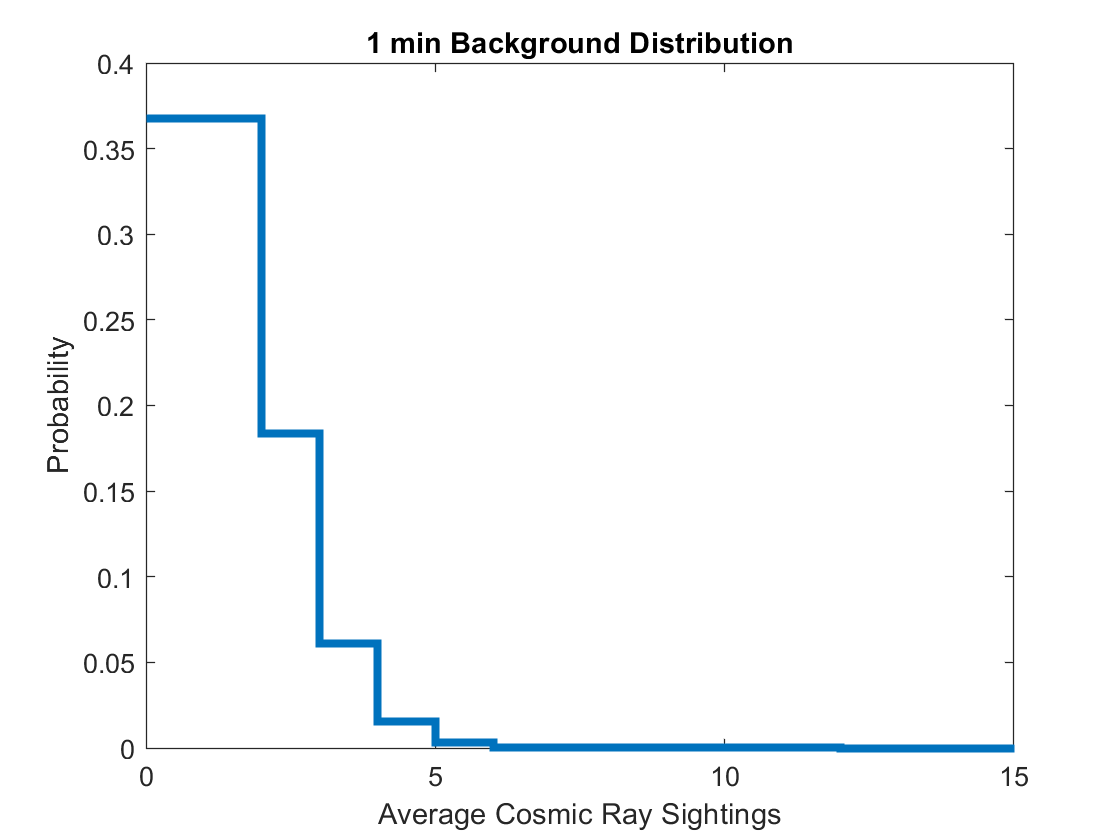

x = 0:1:60;
mindist = makedist("Poisson","lambda",1);
min = pdf(mindist,x);
subplot(1,1,1)
stairs(x,min,"LineWidth",3)
xlim([0,15])
title("1 min Background Distribution")
xlabel("Average Cosmic Ray Sightings")
ylabel("Probability")

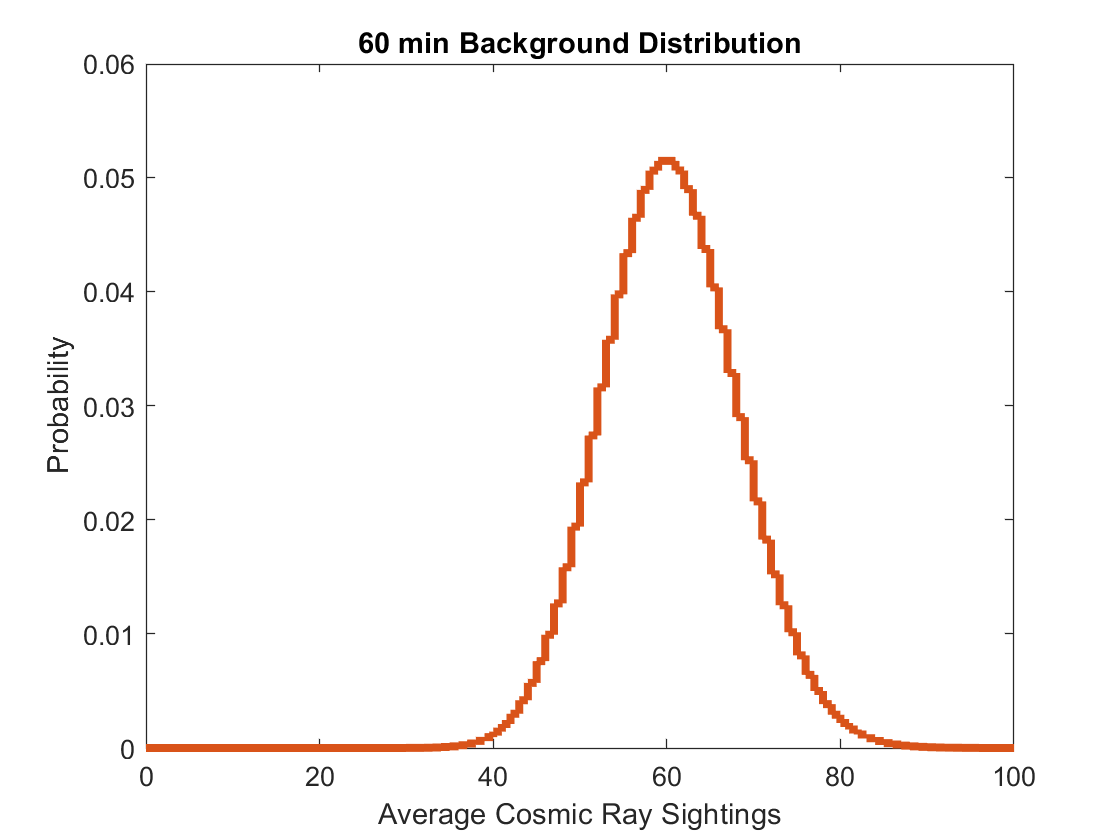

min = min/sum(min);
comb = min;

for i = 2:60
    comb = conv(comb,min,"full");
end

cx = 0*i:1:60*i;
stairs(cx,comb,"LineWidth",3)
xlim([0,100])
title("60 min Background Distribution")
xlabel("Average Cosmic Ray Sightings")
ylabel("Probability")
hold on
hrdist = makedist("Poisson","lambda",60);
hr = pdf(hrdist,cx);
stairs(cx,hr,"LineWidth",3)
hold off

The convolved 60 min distribution exactly overlaps the Poisson distribution with $\lambda =60$ in the graph above, so the sum of n Poisson distributions with condition $\lambda$ is equal to a single Poisson distribution with condition $n\lambda$. 

Therefore, the background distribution after 15 days is: 

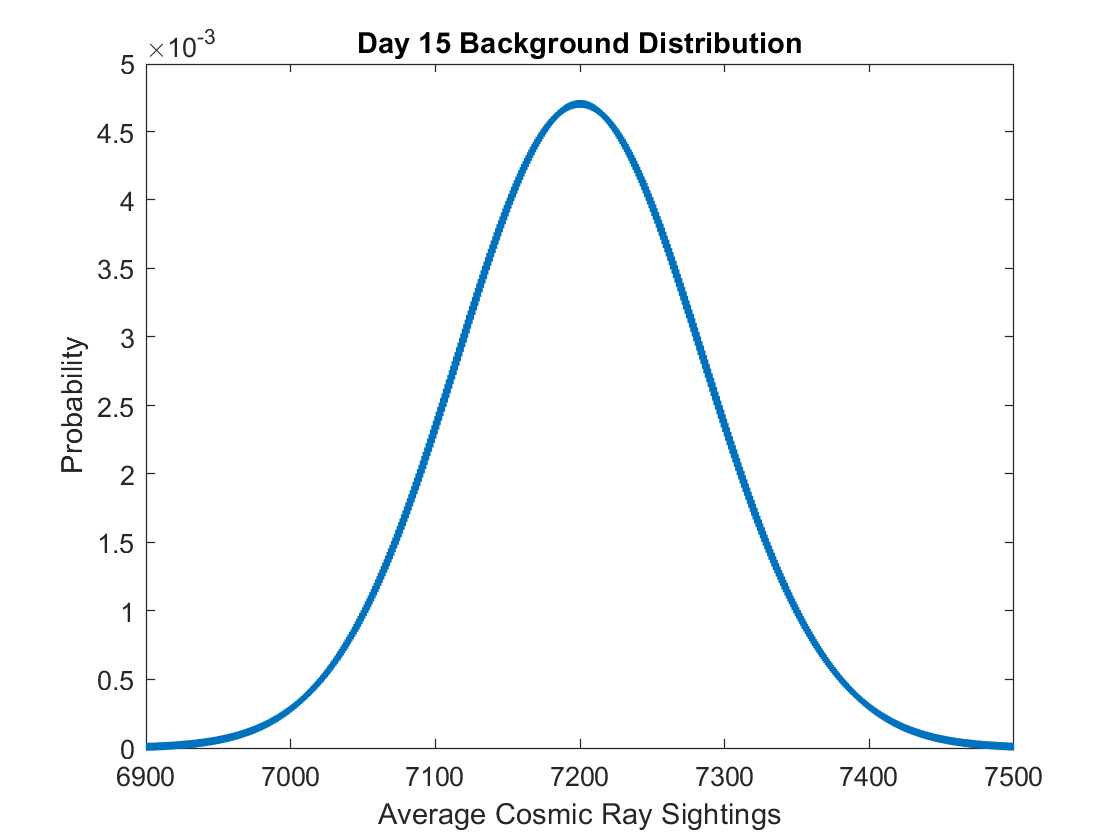

x = 0:1:14400;
day15dist = makedist("Poisson","lambda",7200);
day15 = pdf(day15dist,x);

stairs(x,day15,"LineWidth",3)
xlim([6900,7500])
title("Day 15 Background Distribution")
xlabel("Average Cosmic Ray Sightings")
ylabel("Probability")

*Using Equations to Find the Background*


$$\sum_1^n P\left(\lambda \right)=P\left(n\lambda \right)$$


The sum of n identical poisson distributions is equivalent to a Poisson distribution with condition $n\lambda$. 

#### ANSWERING THE QUESTION MATHEMATICALLY:

To find the probability of observing 6800 cosmic rays, find the area under the curve from 0 to 6800. I sum rather than integrate, since a Poisson distribution is discrete. 


$$\mathrm{prob}=\sum_{k\;=\;0}^{6800} P\left(k\right)$$


Then convert to sigma by finding the sigma on a standard normal distribution corresponding to the probability. 

### 3. Convert to sigma.

prob = cdf(day15dist,6800)

prob = 1.0133e-06

For this problem, I'm calculating probability from 0 to my value rather than from my value to $\infty$ since my observed value is to the left of the mean. To find sigma, I need to calculate the likelihood that the background is as or more signal-like, and summing to the right would give me a value that is not representative of my question. 

sigma = norminv(prob)

sigma = -4.7507

Note that the value of sigma is negative. For symmetric distributions centered at 0, a negative sigma can be avoided by making the probability negative. For this problem, however, that isn't possible since the center of the distribution is a positive integer. The negative sigma just indicates that the probability falls $4\ldotp 75\sigma$ to the left of center on a standard normal distribution. 

My sigma value for 6800 cosmic rays is $4\ldotp 75\sigma$. This means my observation is not significant; conventially, observations must be $5\sigma$ or greater to be considered significant. 